# Deep learning example

This example shows how to classify heartbeat electrocardiogram (ECG) data from the PhysioNet 2017 Challenge using a deep learning approach.

ECGs record the electrical activity of a person's heart over a period of time. Physicians use ECGs to detect visually if a patient's heartbeat is normal or irregular. Atrial fibrillation (AFib) is a type of irregular heartbeat that occurs when the heart's upper chambers, the atria, beat out of coordination with the lower chambers, the ventricles.

This example uses ECG data from the PhysioNet 2017 Challenge. 

The data consists of a set of ECG signals sampled at 300 Hz, divided into two classes:

- Normal (N)

- Atrial fibrillation (A)

This example shows how to automate the classification process using deep learning. The procedure explores a binary classifier that can differentiate Normal ECG signals from signals showing signs of Atrial fibrillation.

Some of the functions used in this livescript require the Deep Learning Toolbox™. If this support package is not installed, the functions provide the download link.

clc;clear;

## Load data

The loading operation adds two variables to the workspace:

- X is a cell array that holds the ECG signals

- Y is a categorical array that holds the corresponding ground-truth labels of the signals.

rng(0); %for reproducibility
data = load('PhysionetData.mat');
X = data.Signals;
Y = data.Labels;

The [histogram](https://it.mathworks.com/help/matlab/ref/matlab.graphics.chart.primitive.histogram.html) shows a high class imbalance.

An imbalance data set can be an issue when training a neural network that could focus only on the majority class.

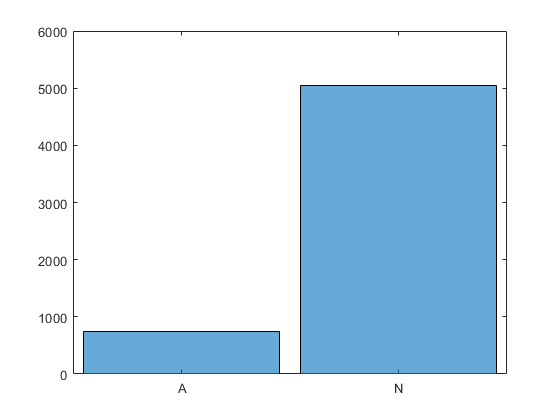

histogram(Y)

The [histogram](https://it.mathworks.com/help/matlab/ref/matlab.graphics.chart.primitive.histogram.html) shows signal lengths. Most of the signals are 9000 samples long.

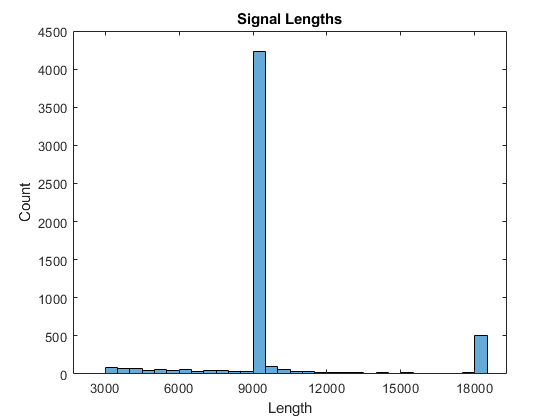

L = cellfun(@length,X);
h = histogram(L);
xticks(0:3000:18000);
xticklabels(0:3000:18000);
title('Signal Lengths')
xlabel('Length')
ylabel('Count')

## Extract features

This example focuses on signals with 9000 samples.

Deep learning  with signals doesn’t perform well on raw data, hence features from sequences are extracted. There are different features which can be chosen, in this example, instantaneous frequency and spectral entropy are used.

[cellfun](https://it.mathworks.com/help/matlab/ref/cellfun.html) is used to apply the [instfreq](https://it.mathworks.com/help/signal/ref/instfreq.html) and [pentropy](https://it.mathworks.com/help/signal/ref/pentropy.html) functions to every cell in the dataset.

The [instfreq](https://it.mathworks.com/help/signal/ref/instfreq.html) function estimates the time-dependent frequency of a signal. It computes the instantaneous frequency of a signal. The function computes a spectrogram using short-time Fourier transforms over time windows. In this example, the function uses 255 time windows.

[pentropy](https://it.mathworks.com/help/signal/ref/pentropy.html) computes the spectral entropy of a signal, which measures how spiky flat the spectrum of a signal is. A signal with a spiky spectrum, like a sum of sinusoids, has low spectral entropy. A signal with a flat spectrum, like white noise, has high spectral entropy. The [pentropy](https://it.mathworks.com/help/signal/ref/pentropy.html) function estimates the spectral entropy based on a power spectrogram. As with the instantaneous frequency estimation case, [pentropy](https://it.mathworks.com/help/signal/ref/pentropy.html) uses 255 time windows to compute the spectrogram.

This section takes some time to exectute. For this reason, it is possible to work with extracted features in the `instfreqTrain.mat` and `pentropyTrain.mat `files,  if `doExtraction` is set to false. 

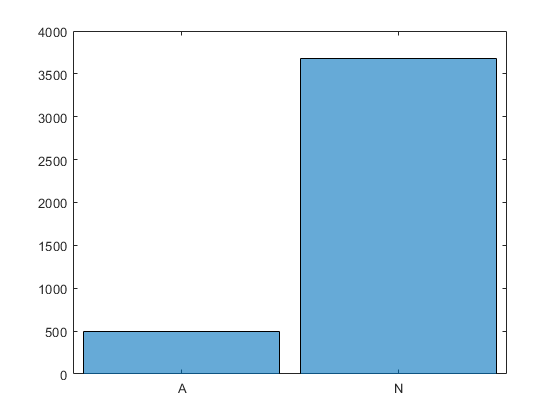

fs = 300;
X=X(L==9000);
Y=Y(L==9000);
histogram(Y) %shows class imabalance

doExtraction =false;

if doExtraction
    instfreqTrain = cellfun(@(x)instfreq(x,fs)',X,'UniformOutput',false);
    pentropyTrain = cellfun(@(x)pentropy(x,fs)',X,'UniformOutput',false);
else
    instfreqTrain = load("instfreqTrain.mat");
    instfreqTrain = instfreqTrain.instfreqTrain;
    pentropyTrain = load("pentropyTrain.mat");
    pentropyTrain = pentropyTrain.pentropyTrain;
    
end

X_freq = cell2mat(instfreqTrain);
X_entrp = cell2mat(pentropyTrain);

## Split data in train, val and test sets

Dataset is split into training, validation and test sets, using the function [dividerand](https://it.mathworks.com/help/deeplearning/ref/dividerand.html)*:*

- The** train set** is the sample of data used to fit the network

- The **validation set** is the sample of data used to provide an unbiased evaluation of a model fit on the training dataset while tuning model wieghts*. *Using a validation partition of data during the training phase may avoid over-fitting. 

- The **test set** is the sample of data used to provide the network performance evaluation

idA = (Y == 'A');
idN = (Y == 'N');

%split data according to label
afibX_freq = X_freq(idA,:);
afibX_entr = X_entrp(idA,:);
afibY = Y(idA,:);

normalX_freq = X_freq(idN,:);
normalX_entr = X_entrp(idN,:);
normalY = Y(idN,:);

%split in train -val-test sets samples from each label
[trainIndA,valIndA,testIndA] = dividerand(size(afibX_freq,1),0.7,0.15,0.15);

XTrainA_freq = afibX_freq(trainIndA,:);
XTrainA_e = afibX_entr(trainIndA,:);
YTrainA = afibY(trainIndA);

XValA_freq  = afibX_freq(valIndA,:);
XValA_e = afibX_entr(valIndA,:);
YValA = afibY(valIndA);

XTestA_freq  = afibX_freq(testIndA,:);
XTestA_e = afibX_entr(testIndA,:);
YTestA = afibY(testIndA);

[trainIndN,valIdN,testIndN] = dividerand(size(normalX_freq,1),0.7,0.15,0.15);

XTrainN_freq  = normalX_freq(trainIndN,:);
XTrainN_e = normalX_entr(trainIndN,:);
YTrainN = normalY(trainIndN);

XValN_freq  = normalX_freq(valIdN,:);
XValN_e = normalX_entr(valIdN,:);
YValN = normalY(valIdN);

XTestN_freq  = normalX_freq(testIndN,:);
XTestN_e = normalX_entr(testIndN,:);
YTestN = normalY(testIndN);

## Data normalization and balancing

To handle the class imbalance, training samples belonging to the minority class are replicated using [repmat](https://it.mathworks.com/help/matlab/ref/repmat.html) (oversampling)*. *

Data balancing step is necessary to avoid that the network will focus only on the majority class.  

Data is normalized using a z-score normalization.  Each column is normalized considering $\frac{\textrm{value}-\mu }{\sigma }$, where $\mu$ is the mean value and $\sigma$ is the standard deviation. 

TrainForNormalize_freq  = [XTrainA_freq ;  XTrainN_freq ];
TrainForNormalize_e = [XTrainA_e;  XTrainN_e];

%compute mean and standard deviation on train set
mu_freq  = mean(TrainForNormalize_freq );
sg_freq  = std(TrainForNormalize_freq );

mu_e = mean(TrainForNormalize_e);
sg_e = std(TrainForNormalize_e);


%balancing train set
szTA = size(XTrainA_e,1);
szTN = size(XTrainN_e,1);

XTrain_freq  = [repmat(XTrainA_freq (1:szTA,:),floor(szTN /szTA),1); XTrainN_freq ];
XTrain_e = [repmat(XTrainA_e(1:szTA,:),floor(szTN /szTA),1); XTrainN_e];
YTrain = [repmat(YTrainA(1:szTA),floor(szTN /szTA),1); YTrainN];

%create validation set
XVal_freq  = [XValA_freq ; XValN_freq ];
XVal_e = [XValA_e; XValN_e];
YVal = [YValA;YValN];
%create test set
XTest_freq  = [XTestA_freq ; XTestN_freq ];
XTest_e = [XTestA_e; XTestN_e];
YTest = [YTestA;YTestN];

%normaliza train, valiation and test sets with the mean and standard
%deviation computed on train set
NormTrain_freq  = (XTrain_freq - mu_freq )./sg_freq ;
NormVal_freq  =  (XVal_freq  - mu_freq )./sg_freq ;
NormTest_freq  = (XTest_freq  - mu_freq )./sg_freq ;

NormTrain_e = (XTrain_e - mu_e)./sg_e;
NormVal_e =  (XVal_e - mu_e)./sg_e;
NormTest_e = (XTest_e - mu_e)./sg_e;

The histogram shows a balanced data set.

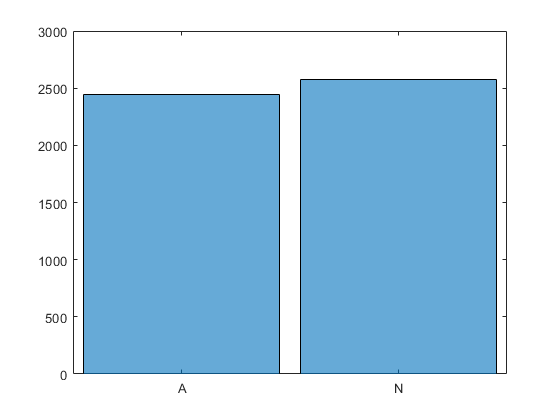

histogram(YTrain)

## Train Network

This example uses a deep neural network. Since XTrain_freq  and XTrain_e are matrices with 255 columns, the featureInputLayer has 255 features. Each [Layer](https://it.mathworks.com/help/deeplearning/ref/nnet.cnn.layer.layer.html) is equipped with [relu](https://it.mathworks.com/help/deeplearning/ref/nnet.cnn.layer.relulayer.html) activation function. 

[trainingoptions](https://it.mathworks.com/help/deeplearning/ref/trainingoptions.html) specifies the training options for the classifier. *MaxEpochs *is set to 100, allowing the network to make 100 passes through the training data. A *MiniBatchSize* of 128 directs the network to look at 128 training samples at a time. 

*Plots* is specified as *training-progress* to generate plots that show a graphic of the training progress as the number of iterations increases. 

The learning rate is set to 0.00001. 

The network *net_e *is trained using *NormTrain_e*. 

The top subplot of the training-progress plot represents the accuracy of training and validation sets. The subplot shows the classification accuracy on each mini-batch for the training set, while validation accuracy is computed with the frequency specified in *ValidationFrequency*. When training progresses successfully, this value typically increases to 100%. 

The bottom subplot displays the loss on training and validation sets.  The bottom subplot shows the cross-entropy loss on each mini-batch for the training set. When training progresses successfully, this value typically decreases towards zero.

`'ValidationPatience' `is the number of times that the loss on the validation set can be larger than or equal to the previously smallest loss before network training stops. During training step, training data is used to update the network parameters, but when validation errors start to increase, training phase should be stopped because the network is no longer generalizing well

dotraining =false;
layers_1 = [featureInputLayer(255,'Name','input'),...
    fullyConnectedLayer(255,'Name','fc1'),...
    reluLayer('Name', 'l1'),...
    fullyConnectedLayer(200,'Name','fc2'),...
    reluLayer('Name', 'l2'),...
    fullyConnectedLayer(150,'Name','fc3'),...
    reluLayer('Name', 'l3'),...
    fullyConnectedLayer(20,'Name','fc4'),...
    reluLayer('Name', 'l4'),...
    fullyConnectedLayer(2,'Name','fc5'),...
    softmaxLayer('Name', 'soft'),...
    classificationLayer('Name', 'cl')...
    ];

batchsize = 128;
options = trainingOptions('adam', ...
    'ExecutionEnvironment', 'auto',...
    'Shuffle', 'every-epoch',...
    'InitialLearnRate',0.00001,...
    'ValidationData',{NormVal_e, YVal},...
    'VerboseFrequency', floor(size(NormTrain_e,1)/batchsize),...
    'ValidationFrequency', floor(size(NormTrain_e,1)/batchsize),...
    'ValidationPatience', 5,...
    'MaxEpochs',100, ...
    'MiniBatchSize',batchsize,...
    'Plots','training-progress');

if dotraining
    net_e = trainNetwork(NormTrain_e,YTrain , layers_1, options);
    save('pretrained_pentropy.mat', 'net_e');
else
    net_e = load('pretrained_pentropy.mat');
    net_e = net_e.net_e;
end

The training phase is repeated using *NormTrain_freq . *

dotraining =false;
batchsize = 128;
options = trainingOptions('adam', ...
    'ExecutionEnvironment', 'auto',...
    'Shuffle', 'every-epoch',...
    'InitialLearnRate',0.00001,...
    'ValidationData',{NormVal_freq , YVal},...
    'VerboseFrequency', floor(size(NormTrain_freq ,1)/batchsize),...
    'ValidationFrequency', floor(size(NormTrain_freq ,1)/batchsize),...
    'ValidationPatience', 5', ...
    'MaxEpochs',100, ...
    'MiniBatchSize',batchsize,...
    'Plots','training-progress');


if dotraining
    net_f  = trainNetwork(NormTrain_freq ,YTrain , layers_1, options);
    save('pretrained_frequency.mat', 'net_f');
else
    net_f = load('pretrained_frequency.mat');
    net_f = net_f.net_f;
end

## Evaluation on test set

The trained networks *net_f* and *net_e *are used to compute the prediction on the test set. 

The function [confusionchart](https://it.mathworks.com/help/stats/confusionchart.html) creates the confusion matrix chart for the classification problem.

if `cm.RowSummary` is specified ad 'row-normalized' the true positive rates and false positive rates are shown for each label. 

pred_e = classify(net_e, NormTest_e);
pred_freq  = classify(net_f, NormTest_freq );
Accuracy_e = sum(pred_e == YTest)/numel(YTest)*100;
disp(['Accuracy using features extracted with pentropy function ' num2str(Accuracy_e)]);

Accuracy using features extracted with pentropy function 83.4131


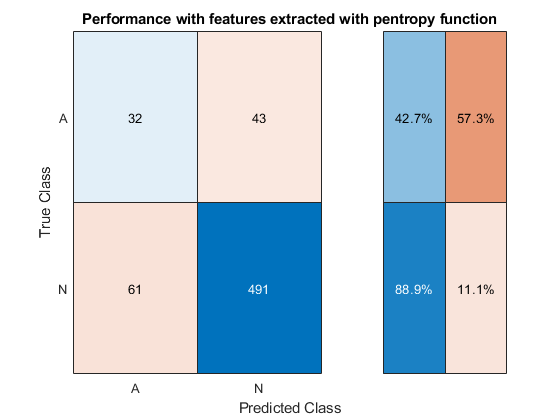

figure
cm = confusionchart(YTest,pred_e);
cm.RowSummary = 'row-normalized';
title('Performance with features extracted with pentropy function');

Accuracy_freq  = sum(pred_freq  == YTest)/numel(YTest)*100;
disp(['Accuracy using features extracted with instfreq function ' num2str(Accuracy_freq )]);

Accuracy using features extracted with instfreq function 82.4561


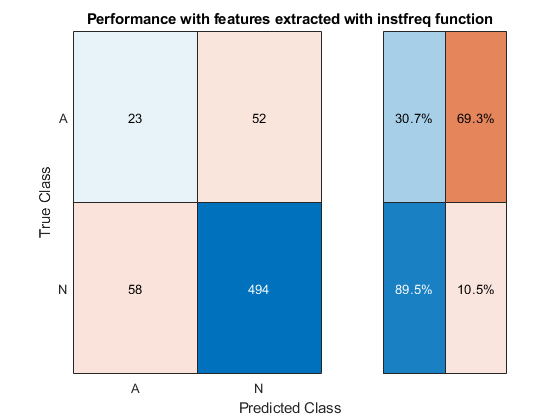

figure
cm = confusionchart(YTest,pred_freq );
cm.RowSummary = 'row-normalized';
title('Performance with features extracted with instfreq function');

## Further Practice

- The performance of the networks seems to be affected by the problem of class imbalance. What happens if the validation set is also balanced by replicating samples belonging to the minority class?

- Another balancing technique is to consider a subset of the instances belonging to the majority class (undersampling). What happens if this technique is implemented?

- Try to modify network architecture using** Deep Network Designer app (**DND).

To open the DND app go to the **Apps** tab, under **Machine Learning and Deep Learning**, click the  icon. Alternatively, you can open the app from the command line [`deepNetworkDesigner`](https://uk.mathworks.com/help/deeplearning/ug/build-networks-with-deep-network-designer.html)

## Further readings

- [confusionmat](https://it.mathworks.com/help/stats/confusionmat.html)

- [instfreq](https://it.mathworks.com/help/signal/ref/instfreq.html)

- [pentropy](https://it.mathworks.com/help/signal/ref/pentropy.html)

- [dividerand](https://it.mathworks.com/help/deeplearning/ref/dividerand.html)

- [deepNetworkDesigner](https://it.mathworks.com/help/deeplearning/ref/deepnetworkdesigner-app.html)

- [Layer](https://it.mathworks.com/help/deeplearning/ref/nnet.cnn.layer.layer.html)

- [trainingoptions](https://it.mathworks.com/help/deeplearning/ref/trainingoptions.html)

- [histogram](https://it.mathworks.com/help/matlab/ref/matlab.graphics.chart.primitive.histogram.html)

- [cellfun](https://it.mathworks.com/help/matlab/ref/cellfun.html)

- [repmat](https://it.mathworks.com/help/matlab/ref/repmat.html)

- [relu](https://it.mathworks.com/help/deeplearning/ref/nnet.cnn.layer.relulayer.html)